
clear;

csvFolderName = "trekking";
clockTimeLimit = 45 % 体験時間 (s)

clockTimeLimit = 45

period = 3.5; % 歩行周期 (s)

legForwardTimeRate = 3; % 足スライダ前進 時間比
legBackwardTimeRate = 4; % 足スライダ後退 時間比

stockForwardTimeRate = 3; % ストックスライダ前進 時間比
stockBackwardTimeRate = 4; % ストックスライダ後退 時間比

upTimeRate = 1; % 伸縮 持ち上げ 時間比
downTimeRate = 1; % 伸縮 降下 時間比

stockFlyingTimeRate = 3; % ストック空中時間比
stockGroundTimeRate = 4; % ストック接地時間比

tiltBackwardTimeRate = stockForwardTimeRate;
tiltForwardTimeRate = stockBackwardTimeRate;

liftLength = 30; % 椅子 リフト長 単位 (mm)
pedalLength = 40; % ペダル長 単位 (mm)
seatSlideForwardLength = 100; % 椅子 スライド長 単位 (mm)
seatSlideBackwardLength = 50; % 椅子 スライド長 単位 (mm)
extendLength = 100; % 伸縮長 単位 (mm)
stockSlideForwardLength = 150; % ストック スライド前方向長 単位 (mm)
stockSlideBackwardLength = 100; % ストック スライド後方向長 単位 (mm)
tiltBackwardDeg = 5; % ストック 後傾角度 (deg)
tiltForwardDeg = -10; % ストック 前傾角度 (deg)

stockStartTime = 0;
waitTime = period/2;


stopTime = clockTimeLimit;
stopTable = table(stopTime);
writetable(stopTable, csvFolderName + '\' + "stop.csv");

椅子 リフト

L = liftLength; % スライド長 単位 (mm)
startClockTime = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) + waitTime; % 開始時刻 (s)
if legForwardTimeRate < legBackwardTimeRate
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/3; % 単位 (s)
    deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/3; % 単位 (s)
    deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 2/3; % 単位 (s)
else
    clockTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) + period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
    deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    deltaTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
end
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period/2:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period/2:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

lifter = table(clockTime, deltaTime, absolutePosition, useStiffness)

lifter = 48×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       3.25         0.5              30                0      
       3.75           1               0                0      
          5         0.5              30                0      
        5.5           1               0                0      
       6.75         0.5              30                0      
       7.25           1               0                0      
        8.5         0.5              30                0      
          9           1               0                0      
      10.25         0.5              30                0      
      10.75           1               0                0      
         12         0.5              30                0      
       12.5           1               0                0      
      13.75         0.5              30                0      
      14.25           1           

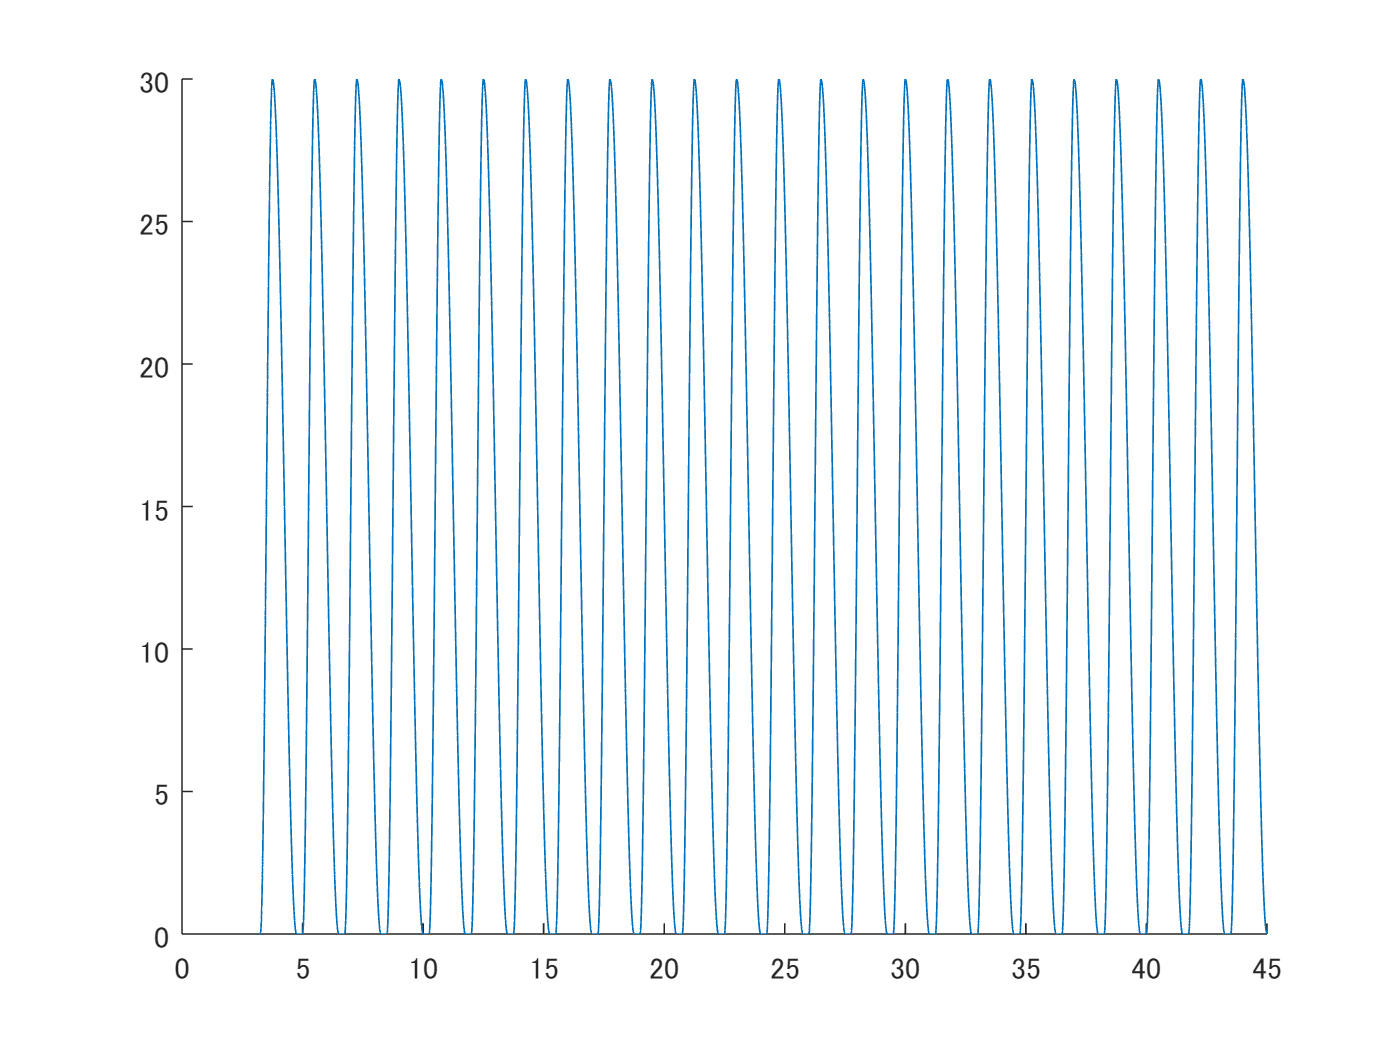

writetable(lifter, csvFolderName + '\' + "lifter.csv");
figure;
[lifter_x, lifter_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = 0 + waitTime; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftPedal = 26×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       1.75        0.75              40                0      
        2.5        0.75               0                0      
       5.25        0.75              40                0      
          6        0.75               0                0      
       8.75        0.75              40                0      
        9.5        0.75               0                0      
      12.25        0.75              40                0      
         13        0.75               0                0      
      15.75        0.75              40                0      
       16.5        0.75               0                0      
      19.25        0.75              40                0      
         20        0.75               0                0      
      22.75        0.75              40                0      
       23.5        0.75        

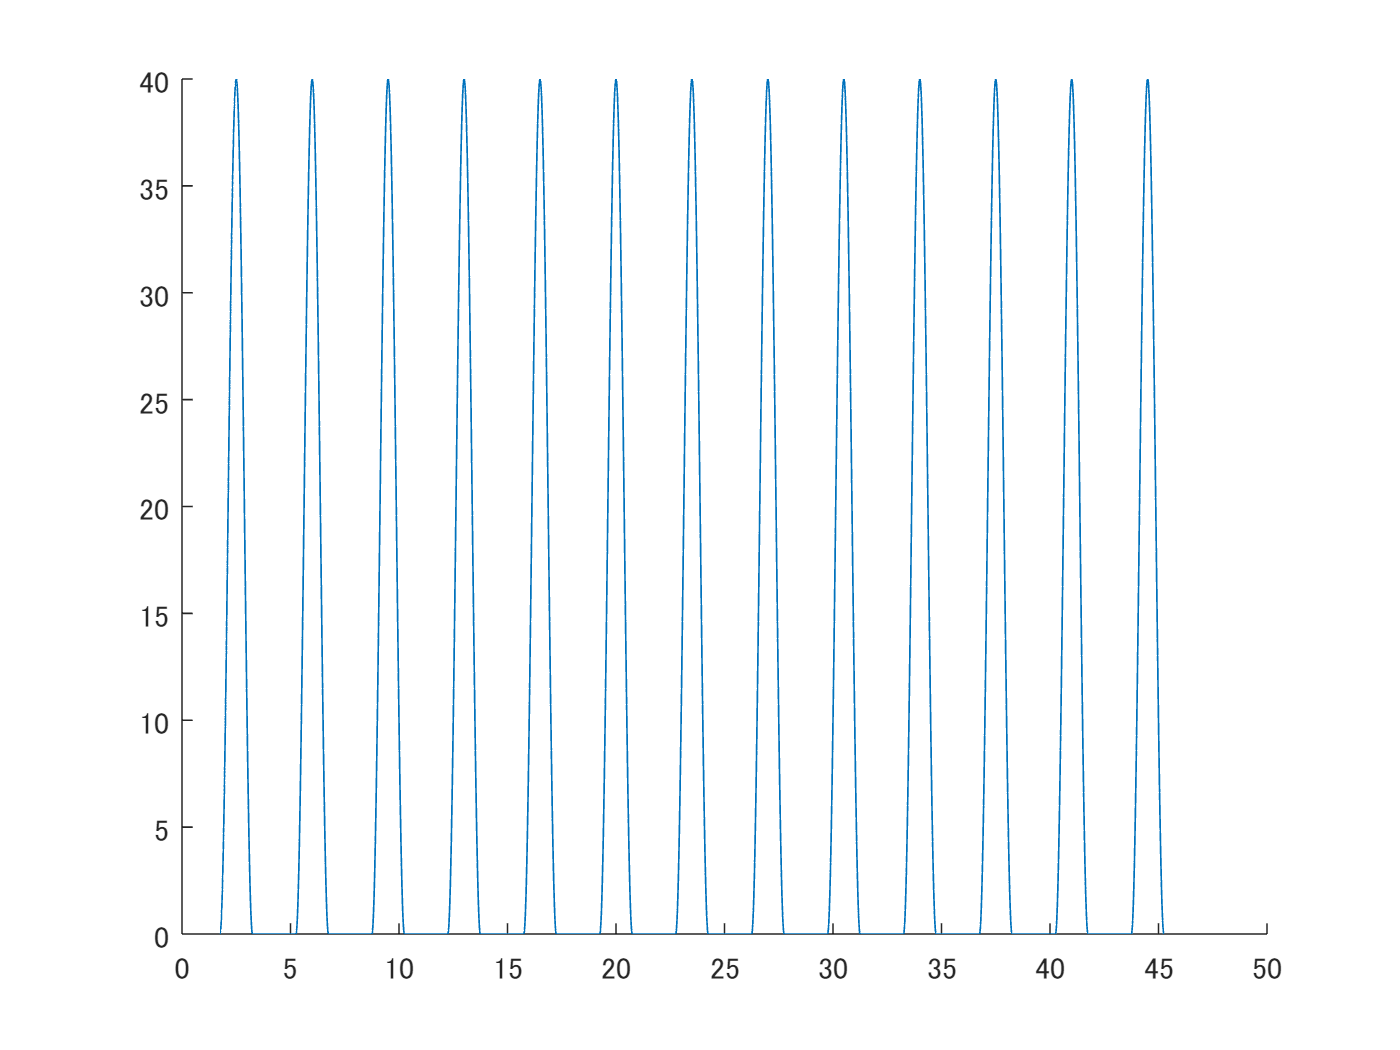

writetable(leftPedal, csvFolderName + '\' + "leftPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[leftPedal_x, leftPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = period/2 + waitTime; % 開始時刻 (s) 
clockTimeU = 0; % 単位 (s)
clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightPedal = 24×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

        3.5        0.75              40                0      
       4.25        0.75               0                0      
          7        0.75              40                0      
       7.75        0.75               0                0      
       10.5        0.75              40                0      
      11.25        0.75               0                0      
         14        0.75              40                0      
      14.75        0.75               0                0      
       17.5        0.75              40                0      
      18.25        0.75               0                0      
         21        0.75              40                0      
      21.75        0.75               0                0      
       24.5        0.75              40                0      
      25.25        0.75       

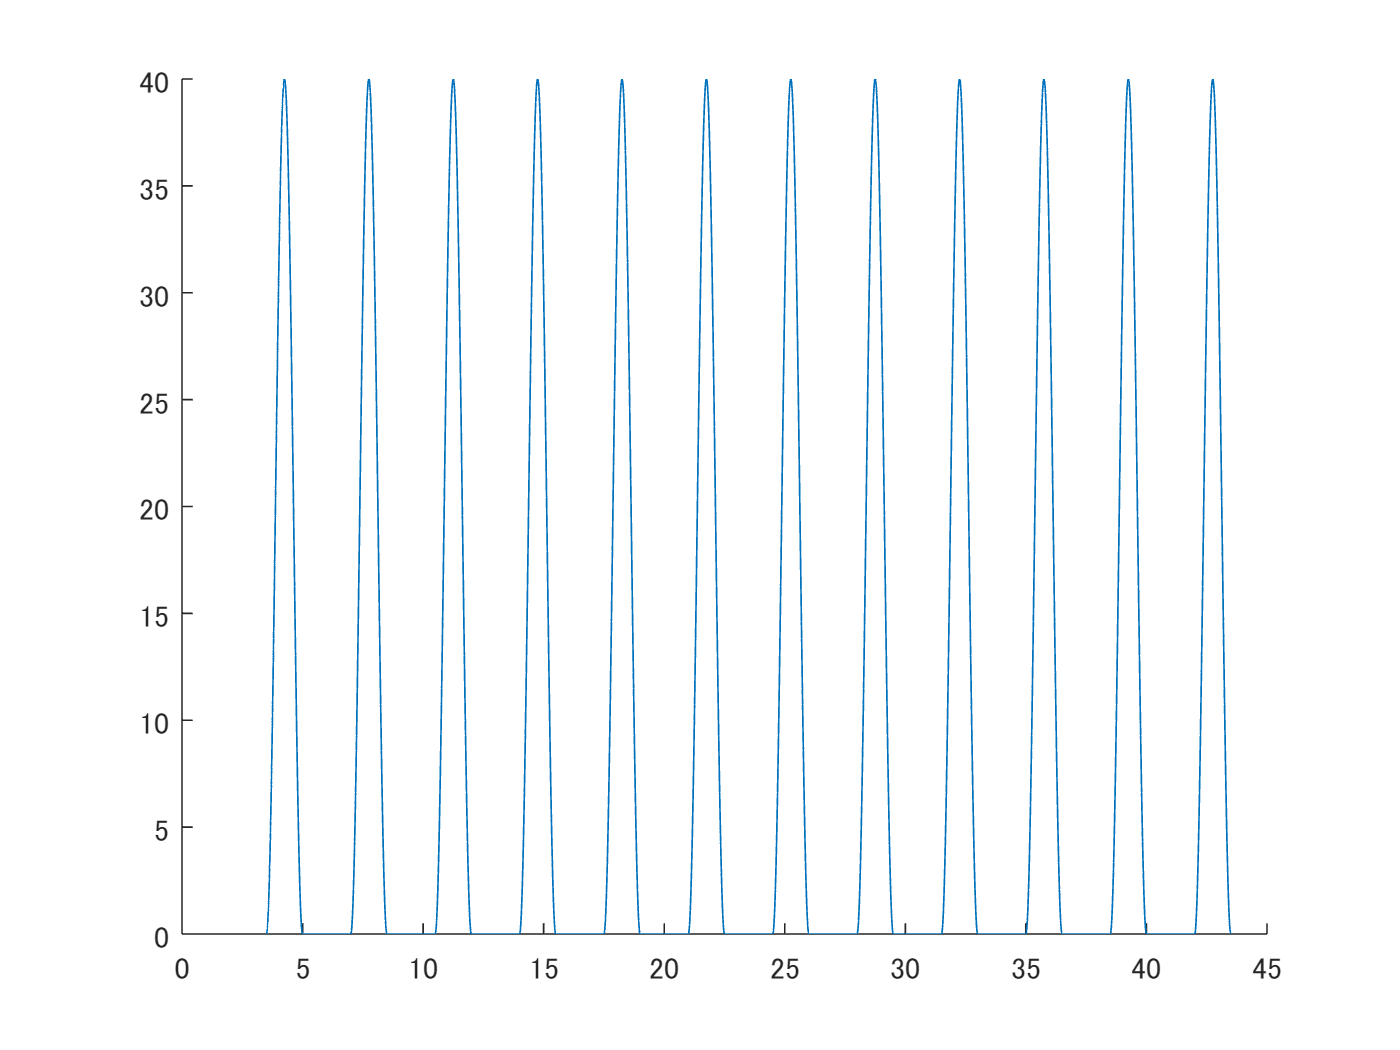

writetable(rightPedal, csvFolderName + '\' + "rightPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[rightPedal_x, rightPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　左　スライダ

startClockTime = 0 + waitTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = seatSlideForwardLength; % 単位 (mm)
positionB = -seatSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatLeftSlider = 24×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       1.75         1.5             100                0      
       3.25           2             -50                0      
       5.25         1.5             100                0      
       6.75           2             -50                0      
       8.75         1.5             100                0      
      10.25           2             -50                0      
      12.25         1.5             100                0      
      13.75           2             -50                0      
      15.75         1.5             100                0      
      17.25           2             -50                0      
      19.25         1.5             100                0      
      20.75           2             -50                0      
      22.75         1.5             100                0      
      24.25           2   

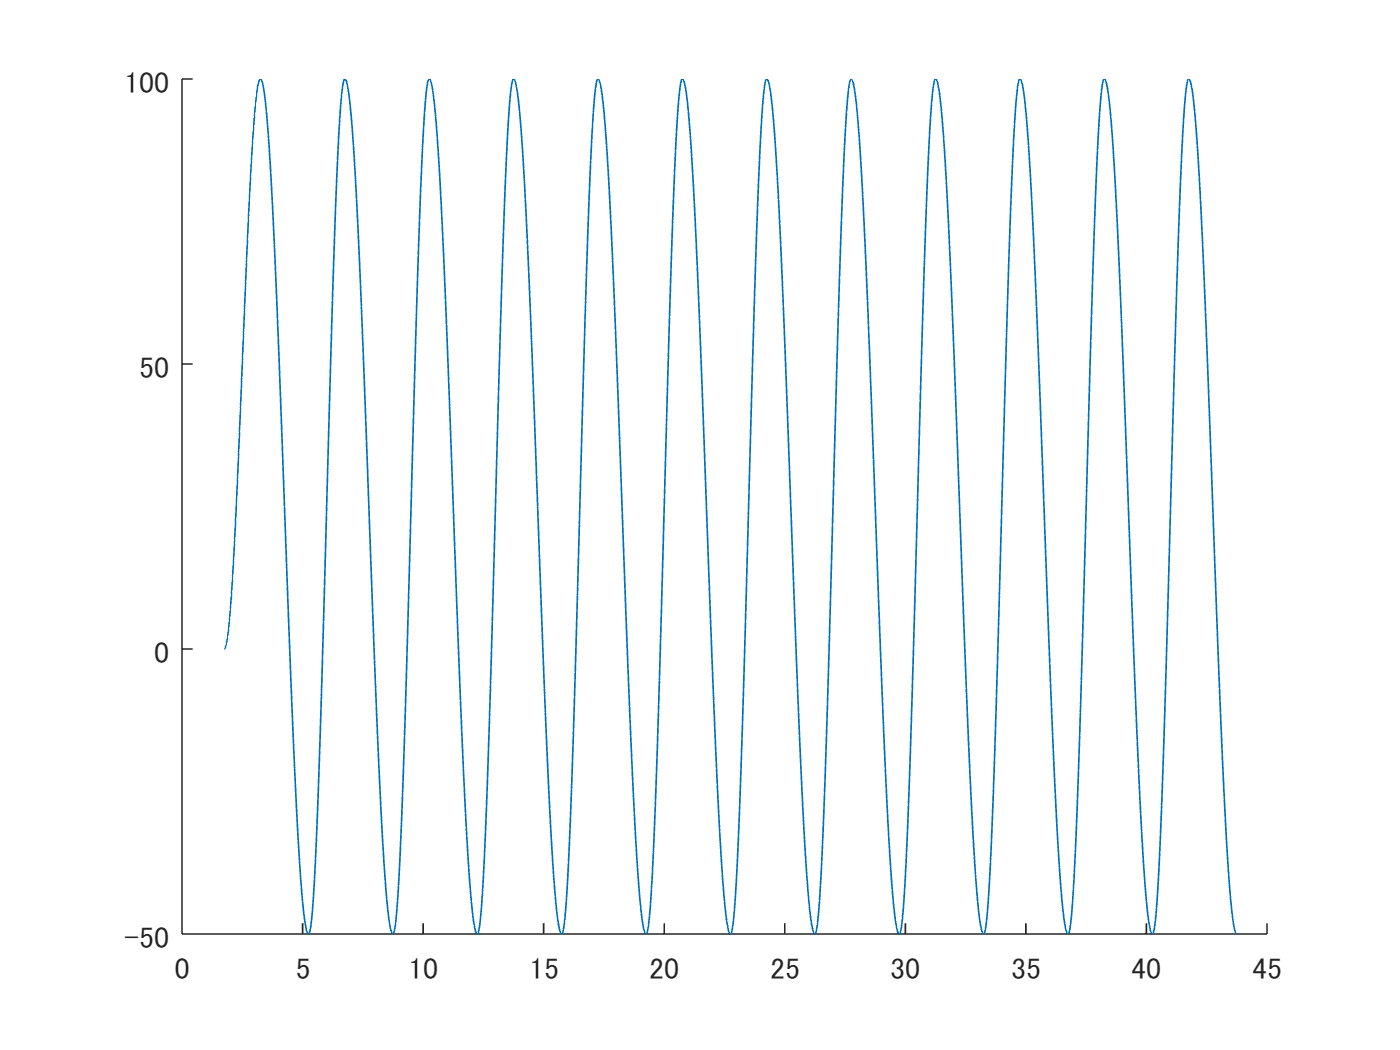

writetable(seatLeftSlider, csvFolderName + '\' + "seatLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatLeftSlider_x, seatLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);


clockTimeVibro = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]))' - 0.5;
LeftFootVibro = table(clockTimeVibro)

LeftFootVibro = 12×1 table
    clockTimeVibro
    ______________

         2.75     
         6.25     
         9.75     
        13.25     
        16.75     
        20.25     
        23.75     
        27.25     
        30.75     
        34.25     
        37.75     
        41.25     


writetable(LeftFootVibro, csvFolderName + '\' + "leftFootVibro.csv");

椅子　右　スライダ

startClockTime = period/2 + waitTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = seatSlideForwardLength; % 単位 (mm)
positionB = -seatSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatRightSlider = 24×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       3.5          1.5             100                0      
         5            2             -50                0      
         7          1.5             100                0      
       8.5            2             -50                0      
      10.5          1.5             100                0      
        12            2             -50                0      
        14          1.5             100                0      
      15.5            2             -50                0      
      17.5          1.5             100                0      
        19            2             -50                0      
        21          1.5             100                0      
      22.5            2             -50                0      
      24.5          1.5             100                0      
        26            2  

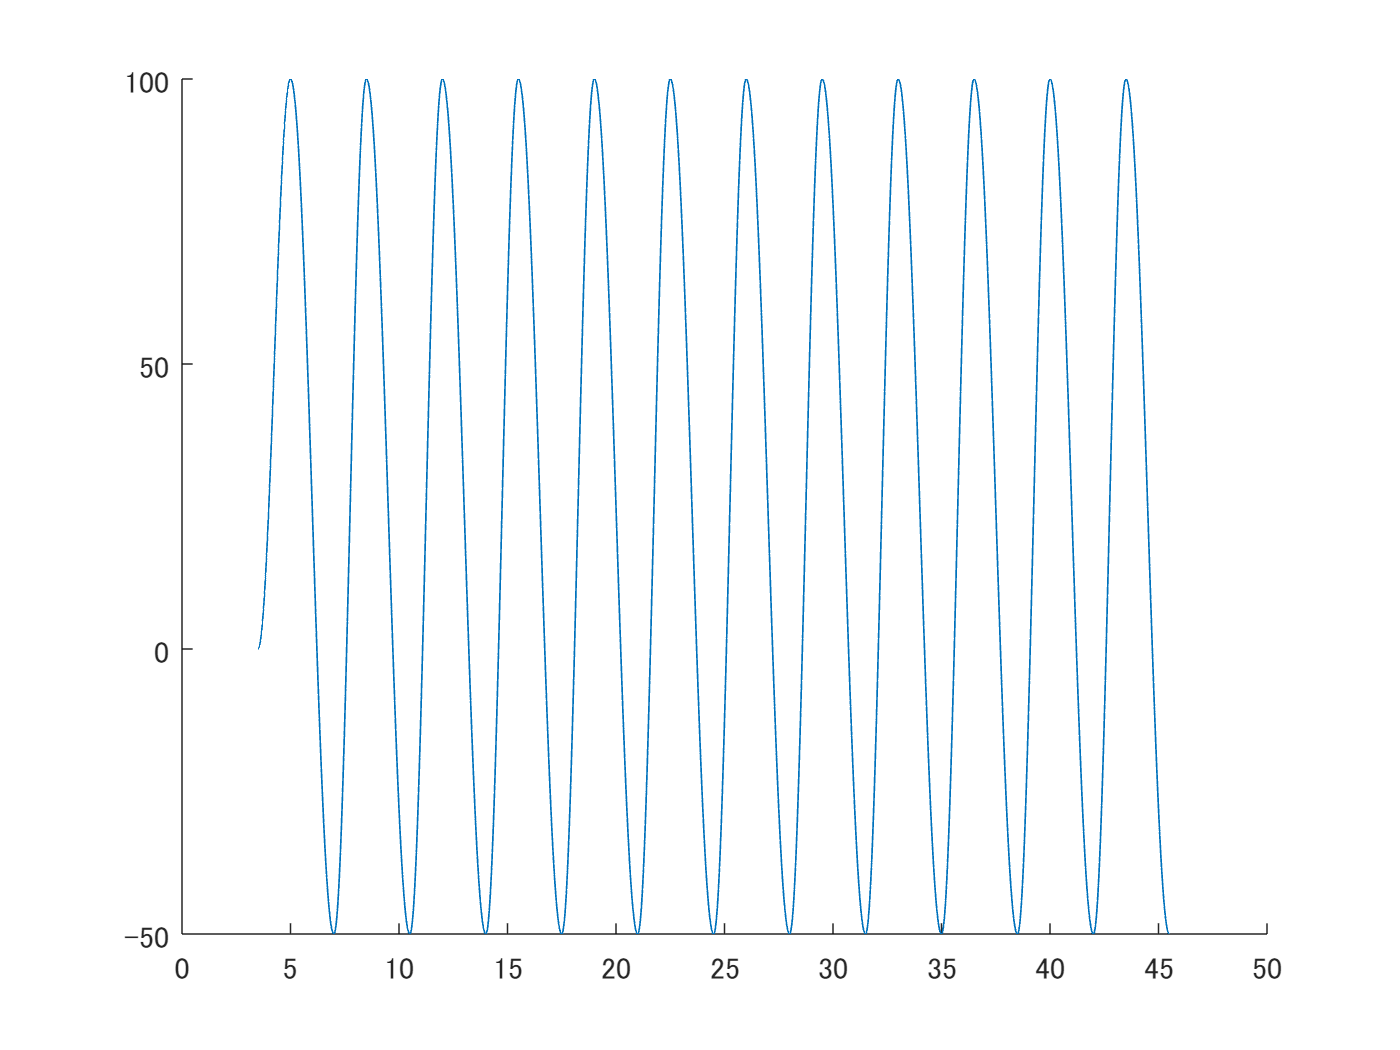

writetable(seatRightSlider, csvFolderName + '\' + "seatRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatRightSlider_x, seatRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

clockTimeVibro = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]))' - 0.5;
RightFootVibro = table(clockTimeVibro)

RightFootVibro = 12×1 table
    clockTimeVibro
    ______________

          4.5     
            8     
         11.5     
           15     
         18.5     
           22     
         25.5     
           29     
         32.5     
           36     
         39.5     
           43     


writetable(RightFootVibro, csvFolderName + '\' + "rightFootVibro.csv");

左ストックの伸縮　登山

L = extendLength; % スライド長 単位 (mm)
startClockTime = stockStartTime + waitTime; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeU = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);
tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList))];
useStiffness = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;
% useStiffness(end+1) = 0;

stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftExtend = 26×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       1.75        0.75             100                0      
        2.5        0.75               0                1      
       5.25        0.75             100                0      
          6        0.75               0                1      
       8.75        0.75             100                0      
        9.5        0.75               0                1      
      12.25        0.75             100                0      
         13        0.75               0                1      
      15.75        0.75             100                0      
       16.5        0.75               0                1      
      19.25        0.75             100                0      
         20        0.75               0                1      
      22.75        0.75             100                0      
       23.5        0.75  

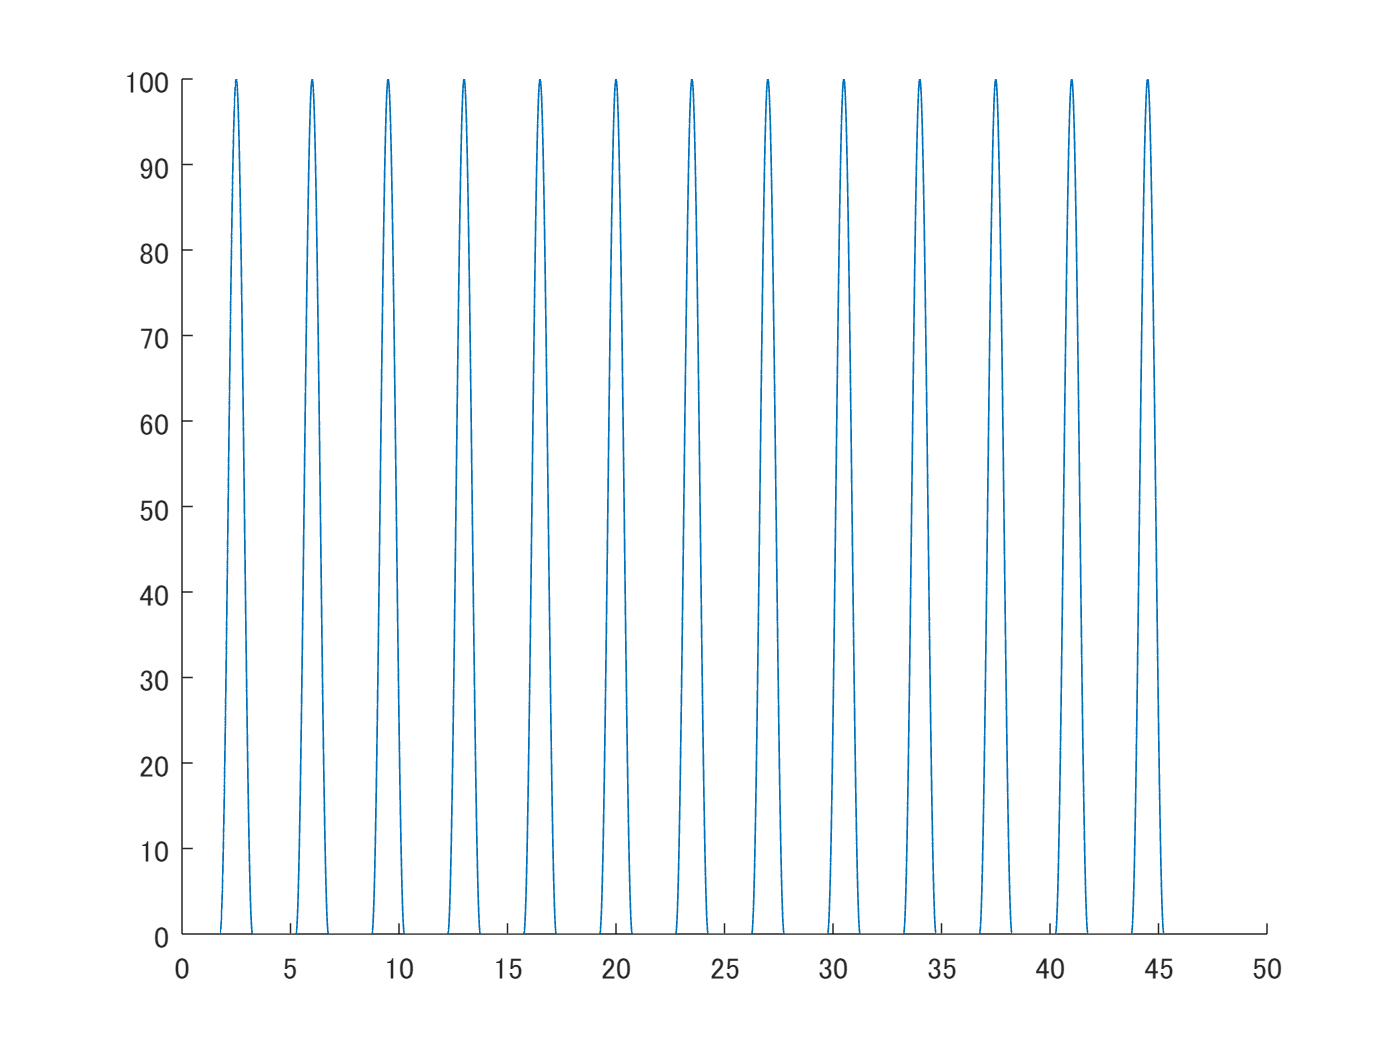

writetable(stockLeftExtend, csvFolderName + '\' + "stockLeftExtend.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮　登山


L = extendLength; % スライド長 単位 (mm)
startClockTime = stockStartTime + period/2 + waitTime; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeU = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);
tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList))];
useStiffness = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;
% useStiffness(end+1) = 0;

stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightExtend = 24×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

        3.5        0.75             100                0      
       4.25        0.75               0                1      
          7        0.75             100                0      
       7.75        0.75               0                1      
       10.5        0.75             100                0      
      11.25        0.75               0                1      
         14        0.75             100                0      
      14.75        0.75               0                1      
       17.5        0.75             100                0      
      18.25        0.75               0                1      
         21        0.75             100                0      
      21.75        0.75               0                1      
       24.5        0.75             100                0      
      25.25        0.75 

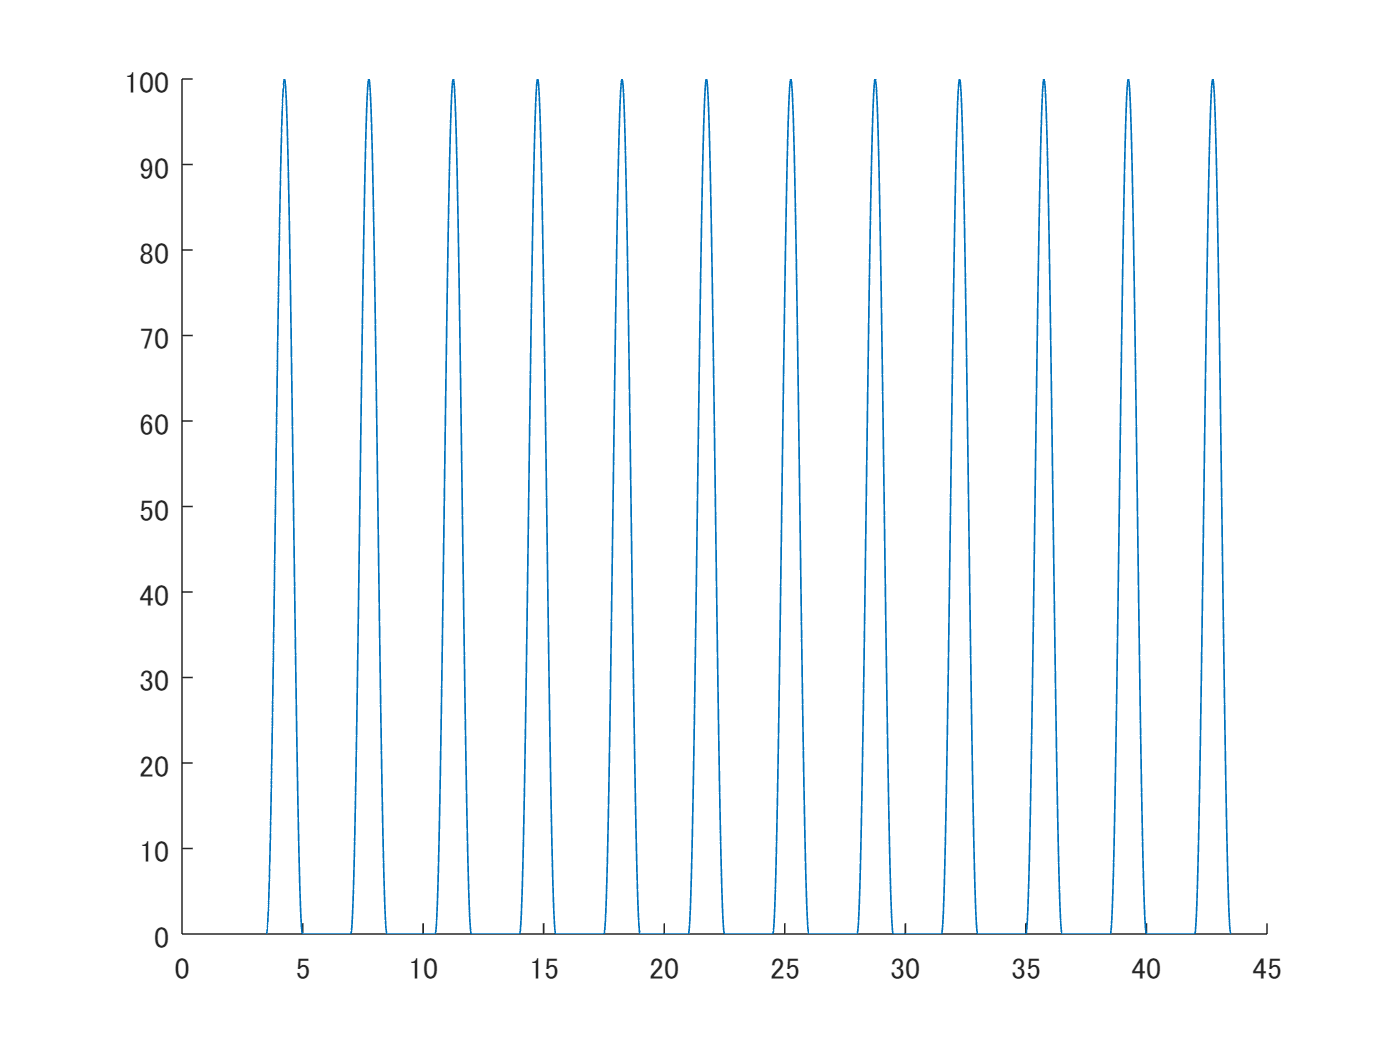

writetable(stockRightExtend, csvFolderName + '\' + "stockRightExtend.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストックのスライダ

startClockTime = stockStartTime + waitTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = stockSlideForwardLength; % 単位 (mm)
positionB = -stockSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftSlider = 24×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       1.75         1.5              150               0      
       3.25           2             -100               0      
       5.25         1.5              150               0      
       6.75           2             -100               0      
       8.75         1.5              150               0      
      10.25           2             -100               0      
      12.25         1.5              150               0      
      13.75           2             -100               0      
      15.75         1.5              150               0      
      17.25           2             -100               0      
      19.25         1.5              150               0      
      20.75           2             -100               0      
      22.75         1.5              150               0      
      24.25           2  

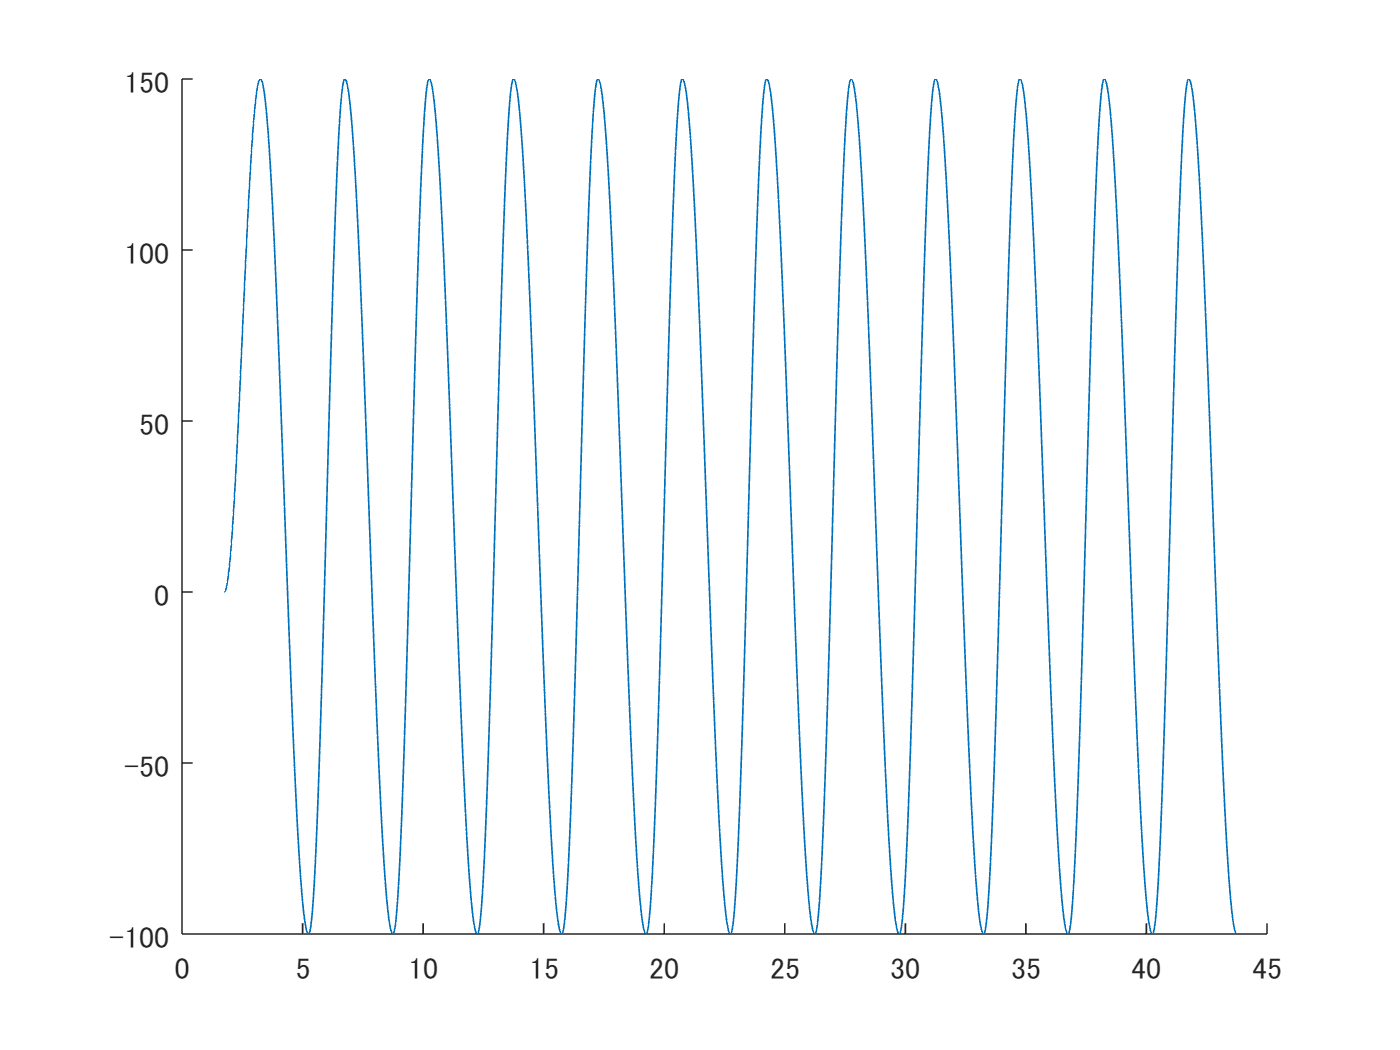

writetable(stockLeftSlider, csvFolderName + '\' + "stockLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockLeftSlider_x, stockLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックのスライダ


L = stockSlideForwardLength; % スライド長 単位 (mm)
startClockTime = stockStartTime + period/2 + waitTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = stockSlideForwardLength; % 単位 (mm)
positionB = -stockSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightSlider = 24×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       3.5          1.5              150               0      
         5            2             -100               0      
         7          1.5              150               0      
       8.5            2             -100               0      
      10.5          1.5              150               0      
        12            2             -100               0      
        14          1.5              150               0      
      15.5            2             -100               0      
      17.5          1.5              150               0      
        19            2             -100               0      
        21          1.5              150               0      
      22.5            2             -100               0      
      24.5          1.5              150               0      
        26            2 

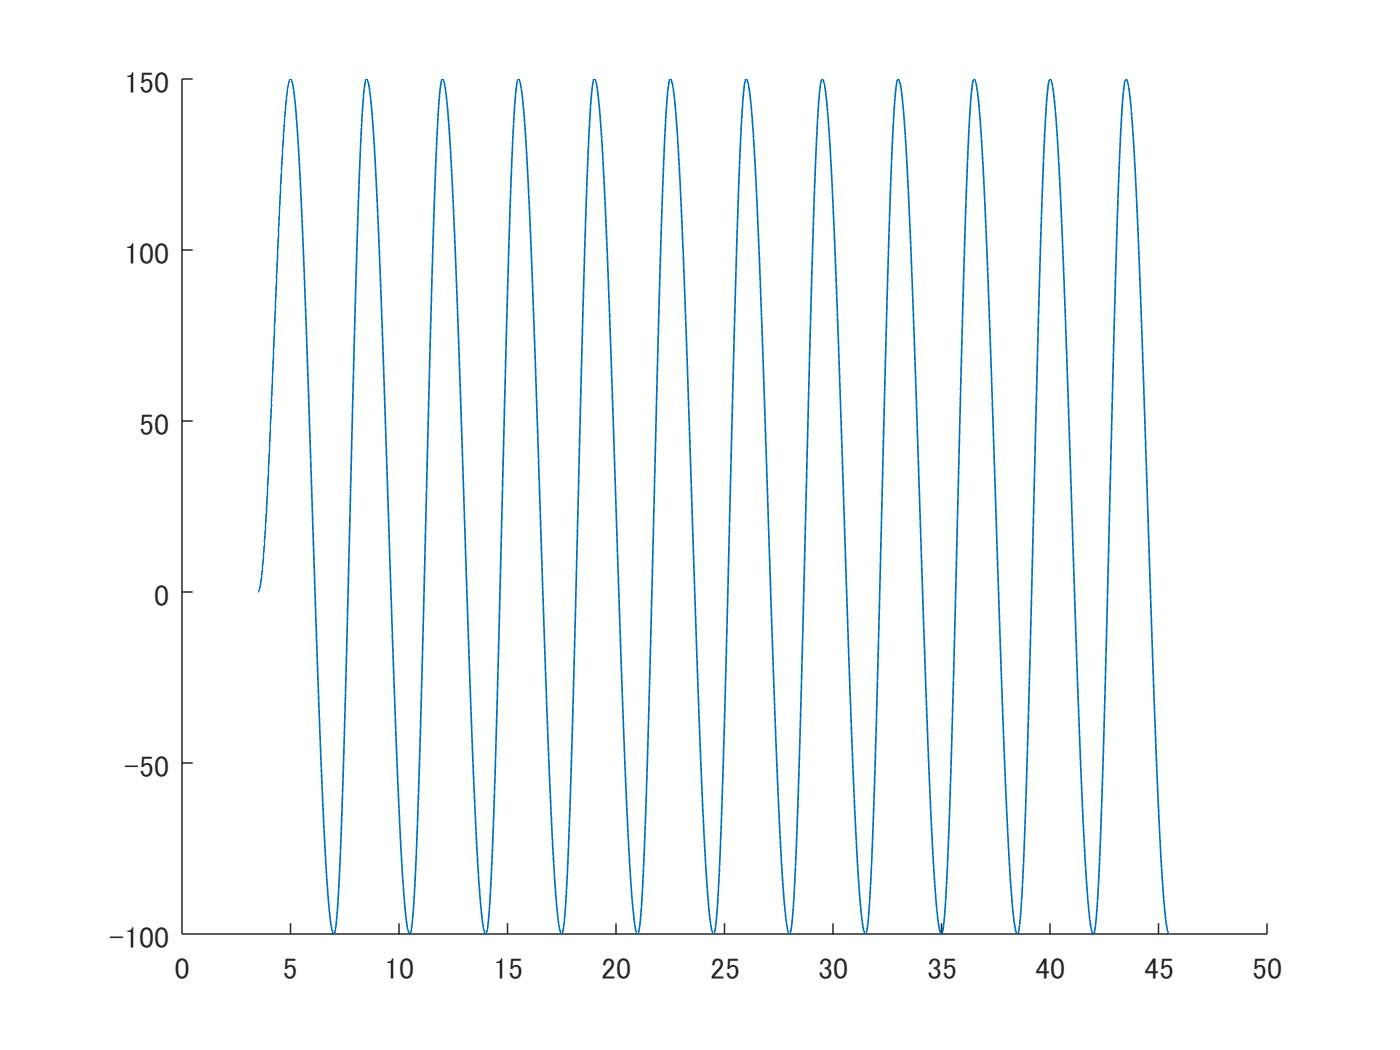

writetable(stockRightSlider, csvFolderName + '\' + "stockRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightSlider_x, stockRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeLeftTilt = stockStartTime + waitTime - period/8; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
% leftTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - leftTiltDeltaTimeF;
leftTiltDelayTimeB = 0;
leftTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeLeftTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeLeftTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = leftTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = leftTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftTilt = 26×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     1.3125         1.5               5                0      
     2.8125           2             -10                0      
     4.8125         1.5               5                0      
     6.3125           2             -10                0      
     8.3125         1.5               5                0      
     9.8125           2             -10                0      
     11.812         1.5               5                0      
     13.312           2             -10                0      
     15.312         1.5               5                0      
     16.812           2             -10                0      
     18.812         1.5               5                0      
     20.312           2             -10                0      
     22.312         1.5               5                0      
     23.812           2         

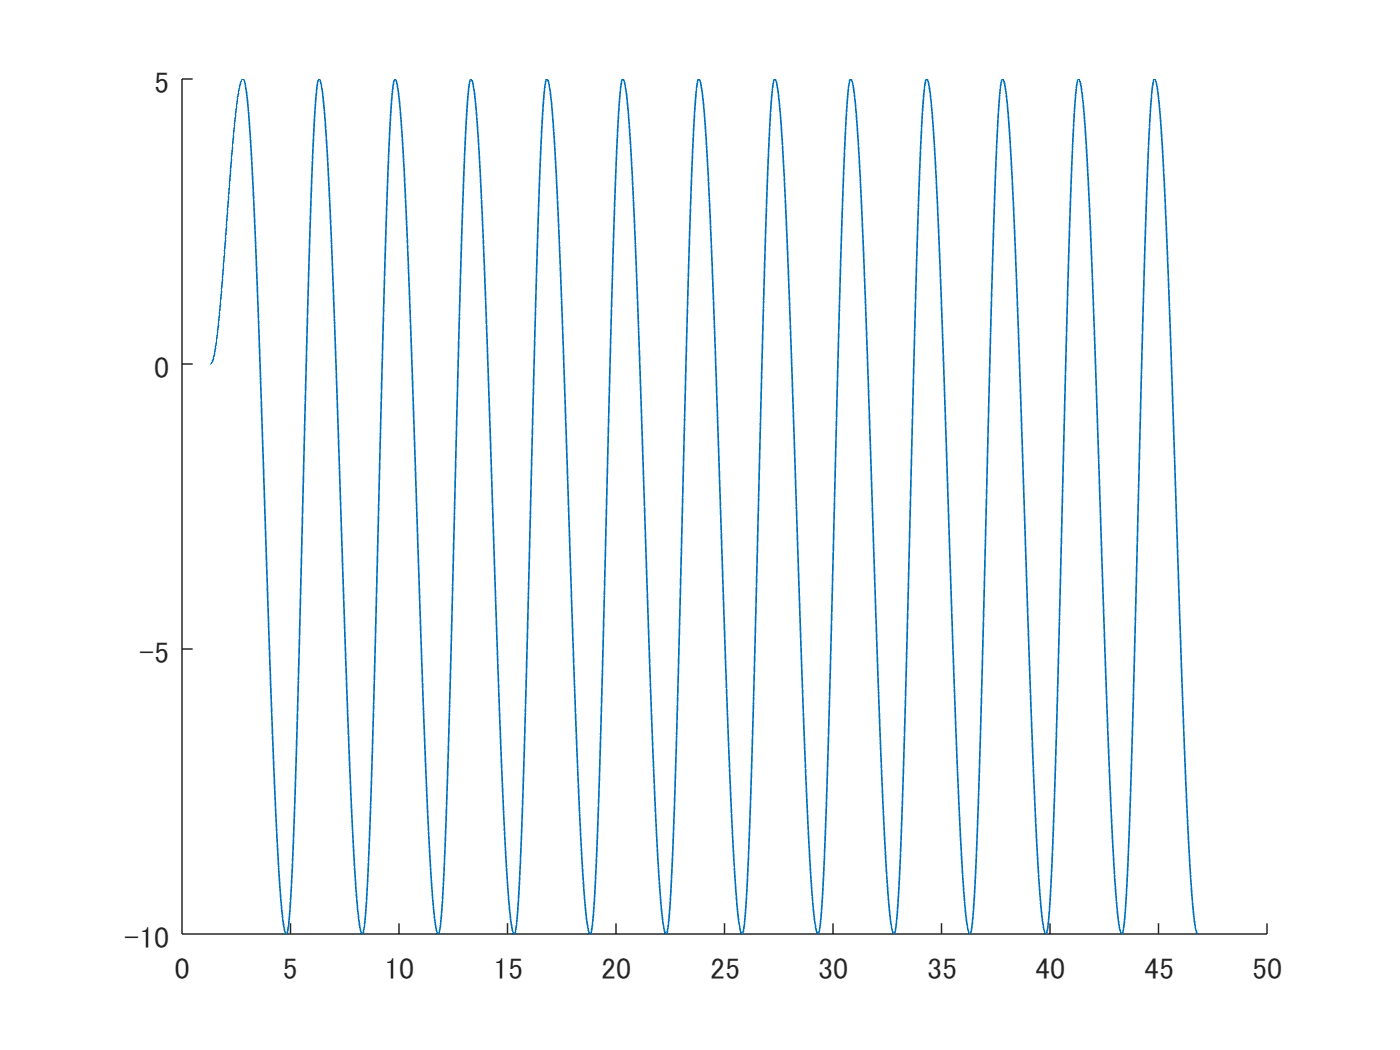

writetable(leftTilt, csvFolderName + '\' + "leftTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[leftTilt_x, leftTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeRightTilt = stockStartTime + period/2 + waitTime - period/8; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
% rightTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - rightTiltDeltaTimeF;
rightTiltDelayTimeB = 0;
rightTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeRightTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeRightTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = rightTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = rightTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightTilt = 24×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     3.0625         1.5               5                0      
     4.5625           2             -10                0      
     6.5625         1.5               5                0      
     8.0625           2             -10                0      
     10.062         1.5               5                0      
     11.562           2             -10                0      
     13.562         1.5               5                0      
     15.062           2             -10                0      
     17.062         1.5               5                0      
     18.562           2             -10                0      
     20.562         1.5               5                0      
     22.062           2             -10                0      
     24.062         1.5               5                0      
     25.562           2        

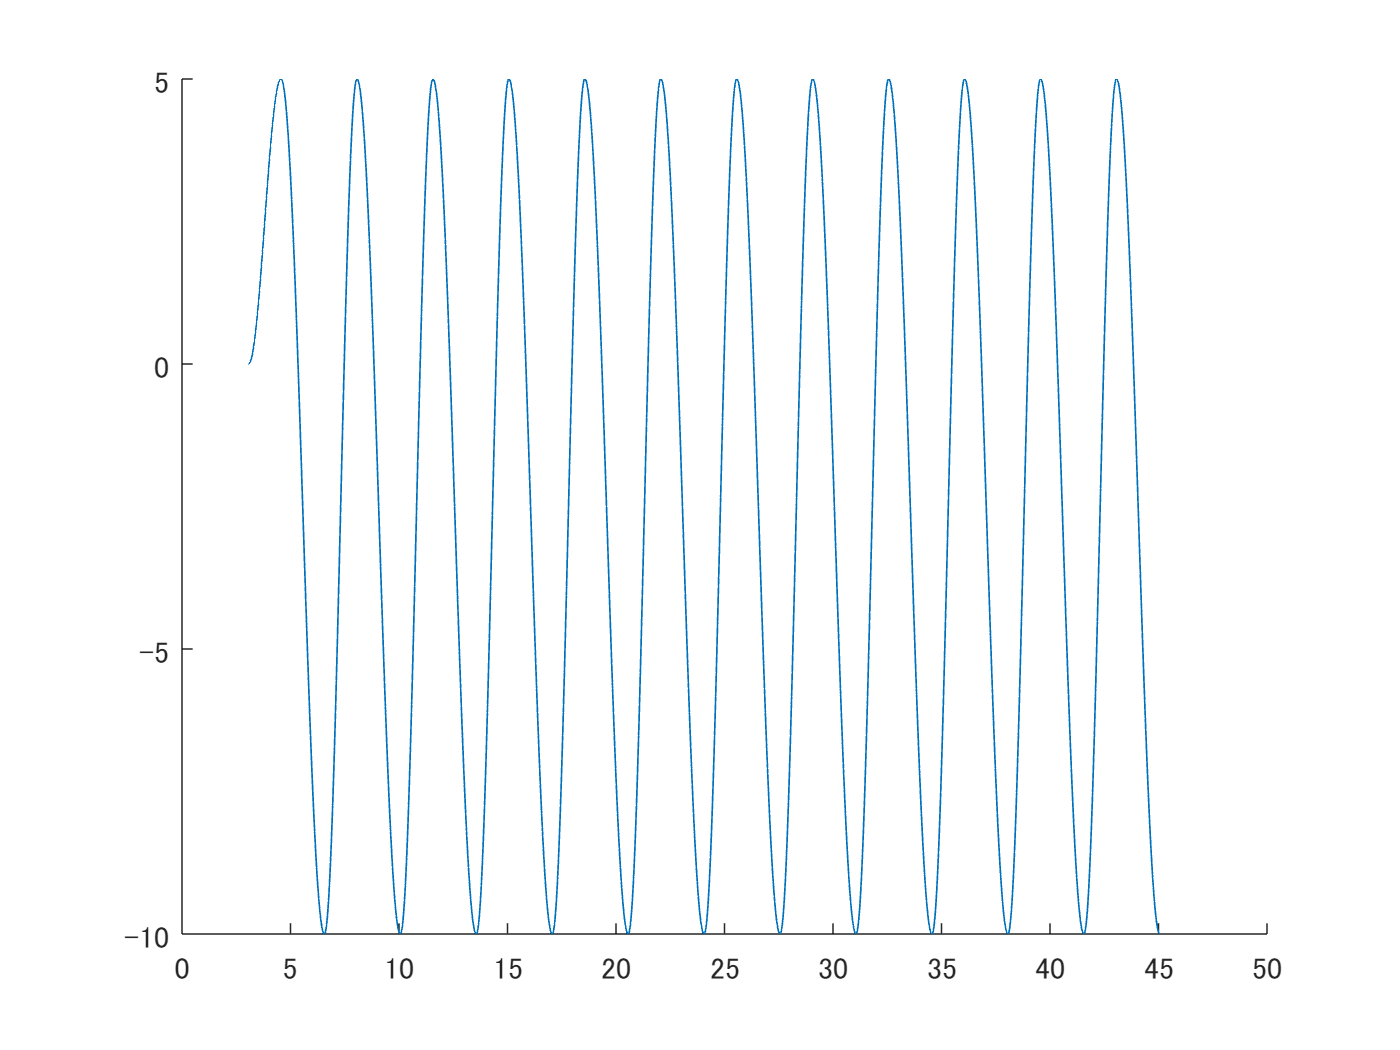

writetable(rightTilt, csvFolderName + '\' + "rightTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[rightTilt_x, rightTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

TiltCSV = table( ...
    period, tiltBackwardDeg, tiltForwardDeg, tiltBackwardTimeRate, tiltForwardTimeRate, startClockTimeLeftTilt, startClockTimeRightTilt, ...
    leftTiltDeltaTimeB, leftTiltDeltaTimeF, rightTiltDeltaTimeB, rightTiltDeltaTimeF, ...
    leftTiltDelayTimeB, leftTiltDelayTimeF, rightTiltDelayTimeB, rightTiltDelayTimeF ...
    )

TiltCSV = 1×15 table
    period    tiltBackwardDeg    tiltForwardDeg    tiltBackwardTimeRate    tiltForwardTimeRate    startClockTimeLeftTilt    startClockTimeRightTilt    leftTiltDeltaTimeB    leftTiltDeltaTimeF    rightTiltDeltaTimeB    rightTiltDeltaTimeF    leftTiltDelayTimeB    leftTiltDelayTimeF    rightTiltDelayTimeB    rightTiltDelayTimeF
    ______    _______________    ______________    ____________________    ___________________    ______________________    _______________________    __________________    __________________    ___________________    ___________________    __________________    __________________    ___________________    ___________________

     3.5             5                -10                   3                       4                     1.3125                    3.0625                    1.5                    2                     1.5                     2                     0                     0                      0                      0    

writetable(TiltCSV, csvFolderName + '\' + 'tilt.csv');

signal_lifter = timeseries(lifter_x, lifter_t, Name='lifter');
signal_leftPedal = timeseries(leftPedal_x, leftPedal_t, Name='leftPedal');
signal_rightPedal = timeseries(rightPedal_x, rightPedal_t, Name='rightPedal');
signal_seatLeftSlider = timeseries(seatLeftSlider_x, seatLeftSlider_t, Name='seatLeftSlider');
signal_seatRightSlider = timeseries(seatRightSlider_x, seatRightSlider_t, Name='seatRightSlider');
signal_stockLeftSlider = timeseries(stockLeftSlider_x, stockLeftSlider_t, Name='stockLeftSlider');
signal_stockRightSlider = timeseries(stockRightSlider_x, stockRightSlider_t, Name='stockRightSlider');
signal_stockLeftExtend = timeseries(stockLeftExtend_x, stockLeftExtend_t, Name='stockLeftExtend');
signal_stockRightExtend = timeseries(stockRightExtend_x, stockRightExtend_t, Name='stockRightExtend');
signal_leftTilt = timeseries(leftTilt_x, leftTilt_t, Name="leftTilt");
signal_rightTilt = timeseries(rightTilt_x, rightTilt_t, Name="rightTilt");

Scenario = Simulink.SimulationData.Dataset;

Scenario{1} = signal_lifter;
Scenario{2} = signal_leftPedal;
Scenario{3} = signal_rightPedal;
Scenario{4} = signal_seatLeftSlider;
Scenario{5} = signal_seatRightSlider;
Scenario{6} = signal_stockLeftExtend;
Scenario{7} = signal_stockRightExtend;
Scenario{8} = signal_stockLeftSlider;
Scenario{9} = signal_stockRightSlider;
Scenario{10} = signal_leftTilt;
Scenario{11} = signal_rightTilt;


% Scenario{2} = SignalStickRightPitch;
% Scenario{2}.Name = 'SignalStickRightPitch';
% Scenario{5} = signal_stockLeftPitch;
% Scenario{5}.Name = 'SignalStickLeftPitch';

save('../../../scenario.mat', 'Scenario');

sim("Simulink.slx");

clear;

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end
